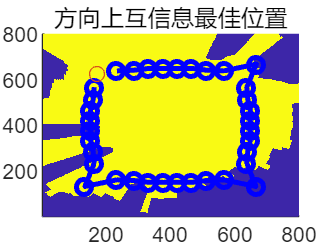



% 参数准备
xI = [x0(1),x0(2)-1];
xF = [row1(1),x0(1)];
% 设置起点startPos和终点destPos

startPos  = xI;
destPos   = xF;

centerAngle = atan2(startPos(2) - BSloc(2), startPos(1) - BSloc(1));  

%% 生成均匀间隔的角度集合
numAngles = 36;  % 设定角度数量（如每20度一个，共36个）
angles = linspace(centerAngle, centerAngle + 2*pi, numAngles + 1);  
angles(end) = [];  % 去掉2*pi，避免重复
    
Boundary = zeros(numAngles,1);
for i = 1:numAngles
   Boundary(i) = Find_Boundary(mod(angles(i),2*pi));
end


measurementPositions = Calculate_meas_loc_eachang(BSloc(1:2),I_Lphi_Mxn,angles,Boundary);
measurementPositions(1,:) = [];
figure;
hold on;
imagesc(LSM');
plot(measurementPositions(:,1), measurementPositions(:,2), 'bo-', 'LineWidth', 2);
title('方向上互信息最佳位置');
scatter(startPos(1),startPos(2));
xlim([1,800]);
ylim([1,800]);

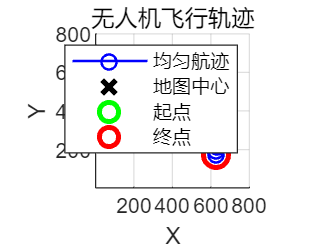


stepLength = 20;  % 固定飞行间隔，适应400范围

% 生成均匀间隔的航迹点
resampledWaypoints = generateUniformTrajectory(BSloc(1:2), startPos, destPos, measurementPositions, stepLength);

% 绘图展示结果
figure; hold on; grid on;
plot(resampledWaypoints(:,1), resampledWaypoints(:,2), 'bo-', 'LineWidth', 1);
plot(BSloc(1), BSloc(2), 'kx', 'MarkerSize', 12, 'LineWidth', 2);
plot(startPos(1), startPos(2), 'go', 'MarkerSize', 10, 'LineWidth', 2);
plot(destPos(1), destPos(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
legend('均匀航迹','地图中心','起点','终点');
title('无人机飞行轨迹');
xlabel('X');
ylabel('Y');
axis equal;
xlim([1,800]);
ylim([1,800]);

## 更新LSM

numMeas = size(resampledWaypoints,1);


for n = 1:numMeas
    LSMlog_prior = LSMlog_posterior;
    xn = [round(resampledWaypoints(n,1)),round(resampledWaypoints(n,2)),UAVheight];
    input_LSM = is_LoSorNLoS(BSloc,xn,smallBldMap);
    flag = -input_LSM + 2;
    dn = norm(xn - BSloc);

    mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(dn);
    var_g = Channel_Para(:,3); 
    var_meas = 0;
    
    zn = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量
    
    [updated_gridn,LSMlog_posterior] = Update_LSM(LSMlog_prior, xn, zn, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图
    updated_grid = [updated_grid;updated_gridn];
    updated_grid = unique(updated_grid,'rows');
end



## Mutual Information Update

LSM_posterior = 1 - 1./(1 + exp(LSMlog_posterior));

[NUM_upa,~] = size(updated_grid);
for i = 1:NUM_upa % LSM地图，计算被更新的栅格角度上的求和的互信息
    xn = [updated_grid(i,1),updated_grid(i,2),UAVheight];
    I_Lphi_Mxn(xn(1),xn(2)) = Compute_I_Lphi_Mxn(LSM_posterior, xn, Channel_Para, BSloc);
end

## Iterative trajectory design

clc;
clear;
load('Base_Data.mat');

% 迭代寻找轨迹，直到满足一定条件结束无人机飞行。
maxInitial_I = max(max(I_Lphi_Mxn));
[row1,col1] = find(I_Lphi_Mxn == maxInitial_I); 
xI = [row1(1),col1(1)];
updated_grid_sum = [];

input_LSM = is_LoSorNLoS(BSloc,[xI,UAVheight],smallBldMap);
flag = -input_LSM + 2;
dI = norm([xI,UAVheight] - BSloc);

mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(dI);
var_g = Channel_Para(:,3); 
var_meas = 0;

zI = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量
[updated_grid,LSM_posterior, LSMlog_posterior] = Update_LSM(LSMlog_prior, [xI,UAVheight], zI, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图
updated_grid_sum = [updated_grid_sum;updated_grid];

[NUM_upa,~] = size(updated_grid);
for i = 1:NUM_upa % LSM地图，计算被更新的栅格角度上的求和的互信息
    xn = [updated_grid(i,1),updated_grid(i,2),UAVheight];
    I_Lphi_Mxn(xn(1),xn(2)) = Compute_I_Lphi_Mxn(LSM_posterior, xn, Channel_Para, BSloc);
end

maxInitial_I = max(max(I_Lphi_Mxn));
[row1,col1] = find(I_Lphi_Mxn == maxInitial_I); 
if size(row1,1) > 1
    [~, idx] = max(norm([row1,col1]-xI));
    xF = [row1(idx),col1(idx)];
else
    xF = [row1,col1];
end

numAngles  = 36; % 离散角度数量
stepLength = 10; % 测量步长

%% 更新初始位置和目的地，寻找寻找I_Lphi_Mxn中的最大值。
for i = 1:4
disp(['已经进行到第',num2str(i),'次迭代飞行']);
updated_grid = [];


% xF = [row1(1),col1(1)];% 可能会有几个最大值。

% while norm(xF - xI) < 10 || i < 5
%     xF = [row1]
% end

[measurementPositions,resampledWaypoints] = Route_Planner_MMI(I_Lphi_Mxn,xI,xF,  BSloc, numAngles, stepLength);

numMeas = size(resampledWaypoints,1);

for n = 1:numMeas
    xI_temp = xI;

    updated_gridn = [];
    LSMlog_prior = LSMlog_posterior;
    xn = [round(resampledWaypoints(n,1)),round(resampledWaypoints(n,2)),UAVheight];
    input_LSM = is_LoSorNLoS(BSloc,xn,smallBldMap);
    flag = -input_LSM + 2;
    dn = norm(xn - BSloc);

    mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(dn);
    var_g = Channel_Para(:,3); 
    var_meas = 0;
    
    zn = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量
    
    [updated_gridn,LSM_posterior,LSMlog_posterior] = Update_LSM(LSMlog_prior, xn, zn, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图
    updated_grid = [updated_grid;updated_gridn];
    updated_grid = unique(updated_grid,'rows');
    
end
updated_grid_sum = [updated_grid_sum;updated_grid];
updated_grid_sum = unique(updated_grid_sum,'rows');
% 对更新后的LSM进行插值后再进行互信息计算.
% LSM_est_mmi = Interpolation_knn(updated_grid, LSM_posterior);


[NUM_upa,~] = size(updated_grid);
for j = 1:NUM_upa % LSM地图，计算被更新的栅格角度上的求和的互信息
    xn = [updated_grid(j,1),updated_grid(j,2),UAVheight];
    I_Lphi_Mxn(xn(1),xn(2)) = Compute_I_Lphi_Mxn(LSM_posterior, xn, Channel_Para, BSloc);
end

xI = xF;

maxInitial_I = max(max(I_Lphi_Mxn));
[row1,col1] = find(I_Lphi_Mxn == maxInitial_I); 
if size(row1,1) > 1
    [~, idx] = max(norm([row1,col1]-xI));
    xF = [row1(idx),col1(idx)];
else
    xF = [row1,col1];
end

end

已经进行到第1次迭代飞行
已经进行到第2次迭代飞行
已经进行到第3次迭代飞行
已经进行到第4次迭代飞行


## 其他基线方案

## 插值，LSM地图补全

LSM_est_mmi = Interpolation_knn(updated_grid_sum, LSM_posterior);

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



% LSM_est_radius = Iterpolation_knn(updated_grid, LSM_posterior);
% LSM_est_

## Plotting

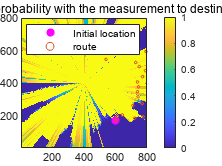


figure;
imagesc(LSM_posterior');
set(gca,'YDir','normal');
colorbar;
title('Posterior LoS probability with the measurement to destination');
hold on;
scatter(xI_temp(1),xI_temp(2),'magenta*','LineWidth',2);
% scatter(resampledWaypoints(:,1),resampledWaypoints(:,2), 4);
scatter(measurementPositions(:,1),measurementPositions(:,2), 4);

legend('Initial location','route');

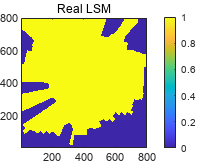


figure;
imagesc(LSM');
set(gca,'YDir','normal');
colorbar;
title('Real LSM');

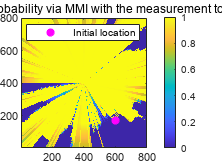


figure;
imagesc(LSM_est_mmi');
set(gca,'YDir','normal');
colorbar;
title('The estimated LoS probability via MMI with the measurement to destination');
hold on;
scatter(xI_temp(1),xI_temp(2),'magenta*','LineWidth',2);
legend('Initial location');

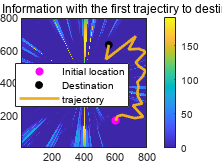



figure;
imagesc(I_Lphi_Mxn');
set(gca,'YDir','normal');
colorbar;
title('Updated Mutual Information with the first trajectiry to destination');
hold on;
scatter(xI_temp(1),xI_temp(2),'magenta*','LineWidth',2);
scatter(xI(1),xI(2),'filled','black','LineWidth',2);
% plot(resampledWaypoints(:,1),resampledWaypoints(:,2),'-', 'LineWidth', 2);
plot(measurementPositions(:,1),measurementPositions(:,2),'-', 'LineWidth', 2);
legend('Initial location','Destination','trajectory');
hold off;


clc;
clear;
load('Base_Data.mat');

% 迭代寻找轨迹，直到满足一定条件结束无人机飞行。
maxInitial_I = max(max(I_Lphi_Mxn));
[row1,col1] = find(I_Lphi_Mxn == maxInitial_I); 
xI = [row1(1),col1(1)];
updated_grid_sum = [];

input_LSM = is_LoSorNLoS(BSloc,[xI,UAVheight],smallBldMap);
flag = -input_LSM + 2;
dI = norm([xI,UAVheight] - BSloc);

mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(dI);
var_g = Channel_Para(:,3); 
var_meas = 0;

zI = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量
[updated_grid,LSM_posterior, LSMlog_posterior] = Update_LSM(LSMlog_prior, [xI,UAVheight], zI, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图
updated_grid_sum = [updated_grid_sum;updated_grid];

[NUM_upa,~] = size(updated_grid);
for i = 1:NUM_upa % LSM地图，计算被更新的栅格角度上的求和的互信息
    xn = [updated_grid(i,1),updated_grid(i,2),UAVheight];
    I_Lphi_Mxn(xn(1),xn(2)) = Compute_I_Lphi_Mxn(LSM_posterior, xn, Channel_Para, BSloc);
end

maxInitial_I = max(max(I_Lphi_Mxn));
[row1,col1] = find(I_Lphi_Mxn == maxInitial_I); 
if size(row1,1) > 1
    [~, idx] = max(norm([row1,col1]-xI));
    xF = [row1(idx),col1(idx)];
else
    xF = [row1,col1];
end

numAngles  = 72; % 离散角度数量
stepLength = 40; % 测量步长
numMeas_sum = 0;
measurementPositions_sum  =  xI ;
%% 更新初始位置和目的地，寻找寻找I_Lphi_Mxn中的最大值。
for i = 1:8
disp(['已经进行到第',num2str(i),'次迭代飞行']);
updated_grid = [];


% xF = [row1(1),col1(1)];% 可能会有几个最大值。

% while norm(xF - xI) < 10 || i < 5
%     xF = [row1]
% end

[measurementPositions,resampledWaypoints] = Route_Planner_MMI(I_Lphi_Mxn,xI,xF,  BSloc, numAngles, stepLength);
measurementPositions_sum = [measurementPositions_sum;resampledWaypoints];

numMeas = size(resampledWaypoints,1);
numMeas_sum = numMeas_sum  +  numMeas;
for n = 1:numMeas
    xI_temp = xI;


    updated_gridn = [];
    LSMlog_prior = LSMlog_posterior;
    xn = [round(resampledWaypoints(n,1)),round(resampledWaypoints(n,2)),UAVheight];
    input_LSM = is_LoSorNLoS(BSloc,xn,smallBldMap);
    flag = -input_LSM + 2;
    dn = norm(xn - BSloc);

    mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(dn);
    var_g = Channel_Para(:,3); 
    var_meas = 0;
    
    zn = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量
    
    [updated_gridn,LSM_posterior,LSMlog_posterior] = Update_LSM(LSMlog_prior, xn, zn, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图
    updated_grid = [updated_grid;updated_gridn];
    updated_grid = unique(updated_grid,'rows');
    
end
updated_grid_sum = [updated_grid_sum;updated_grid];
updated_grid_sum = unique(updated_grid_sum,'rows');
% 对更新后的LSM进行插值后再进行互信息计算.
% LSM_est_mmi = Interpolation_knn(updated_grid, LSM_posterior);


[NUM_upa,~] = size(updated_grid);
for j = 1:NUM_upa % LSM地图，计算被更新的栅格角度上的求和的互信息
    xn = [updated_grid(j,1),updated_grid(j,2),UAVheight];
    I_Lphi_Mxn(xn(1),xn(2)) = Compute_I_Lphi_Mxn(LSM_posterior, xn, Channel_Para, BSloc);
end

xI = xF;

maxInitial_I = max(max(I_Lphi_Mxn));
[row1,col1] = find(I_Lphi_Mxn == maxInitial_I); 
if size(row1,1) > 1
    [~, idx] = max(norm([row1,col1]-xI));
    xF = [row1(idx),col1(idx)];
else
    xF = [row1,col1];
end

end

已经进行到第1次迭代飞行
已经进行到第2次迭代飞行
已经进行到第3次迭代飞行
已经进行到第4次迭代飞行
已经进行到第5次迭代飞行
已经进行到第6次迭代飞行


已经进行到第7次迭代飞行
已经进行到第8次迭代飞行
已经进行到第9次迭代飞行
已经进行到第10次迭代飞行
已经进行到第11次迭代飞行


已经进行到第12次迭代飞行
已经进行到第13次迭代飞行
已经进行到第14次迭代飞行
已经进行到第15次迭代飞行
已经进行到第16次迭代飞行
已经进行到第17次迭代飞行
已经进行到第18次迭代飞行
已经进行到第19次迭代飞行


已经进行到第20次迭代飞行
已经进行到第21次迭代飞行
已经进行到第22次迭代飞行
已经进行到第23次迭代飞行
已经进行到第24次迭代飞行
已经进行到第25次迭代飞行
已经进行到第26次迭代飞行
已经进行到第27次迭代飞行
已经进行到第28次迭代飞行
已经进行到第29次迭代飞行
已经进行到第30次迭代飞行


已经进行到第31次迭代飞行
已经进行到第32次迭代飞行
已经进行到第33次迭代飞行
已经进行到第34次迭代飞行
已经进行到第35次迭代飞行


已经进行到第36次迭代飞行


LSM_est_mmi = Interpolation_knn(updated_grid_sum, LSM_posterior);

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



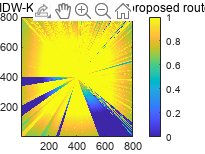


figure;
imagesc(LSM_est_mmi');
set(gca,'YDir','normal');
colorbar;
title('The estimated LSM with IDW-KNN travelling the proposed route to destination');

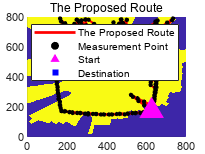




% measurementPositions_sum = unique(measurementPositions_sum,'rows');
% measurementPositions_sum = round(measurementPositions_sum);
figure;
hold on;
imagesc(LSM');
set(gca,'YDir','normal');
box on;



plot(measurementPositions_sum(:,1),measurementPositions_sum(:,2),'-','LineWidth',2,'color','r');
sz3 = 12;
scatter(measurementPositions_sum(:,1),measurementPositions_sum(:,2),sz3,'filled','black');

sz1 = 256;
scatter(measurementPositions_sum(1,1),measurementPositions_sum(1,2),sz1,'filled','^','MarkerFaceColor','magenta');
sz2 = 296;
scatter(measurementPositions_sum(end,1),measurementPositions_sum(end,2),sz1,'filled','square','MarkerFaceColor','b');
xlim([0,800]);
ylim([0,800]);
title('The Proposed Route');
legend('The Proposed Route','Measurement Point','Start','Destination');

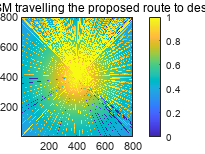



figure;
imagesc(LSM_posterior');
set(gca,'YDir','normal');
colorbar;
title('The estimated LSM travelling the proposed route to destination');

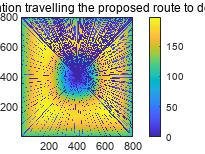


figure;
imagesc(I_Lphi_Mxn');
set(gca,'YDir','normal');
colorbar;
title('The Mutual Information travelling the proposed route to destination');

## Montercalo计算性能曲线

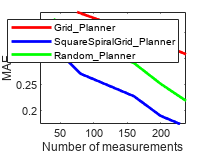

% 有不确定度信息熵和MAE两种指标
% 先在单种地图上进行蒙特卡洛测试


num_of_meas_sum = 240;
num_of_meas_interval = 40; % 测量数量间隔

% num_of_meas = 40:num_of_meas_interval:num_of_meas_sum;
stepLength = 40;

route_plan_baseline = Route_planner_baseline;
measurementPositions_b1 = route_plan_baseline.Grid_planner(LSM,stepLength);
measurementPositions_b2 = route_plan_baseline.SquareSpiralGrid_planner(LSM,stepLength);
measurementPositions_b3 = route_plan_baseline.Random_planner(LSM,stepLength,num_of_meas_sum);
% MAE1 = zeros(floor(num_of_meas_sum./num_of_meas_interval),1);
% H1 = zeros(floor(num_of_meas_sum./num_of_meas_interval),1);

MAE1_M = [];
H1_M = [];
MAE2_M = [];
H2_M = [];
MAE3_M = [];
H3_M = [];
num_Montercalo = 2;

for m = 1:num_Montercalo
    num_of_meas = 0;

%     measurementPositions_b1_m1 = measurementPositions_b1(1:num_of_meas(i),:);
%     measurementPositions_b2_m2 = measurementPositions_b2(1:num_of_meas(i),:);
%     measurementPositions_b3_m3 = measurementPositions_b3(1:num_of_meas(i),:);

    LSMlog_prior1 = log(LSM_initial./(1 - LSM_initial + eps));
    LSMlog_prior2 = log(LSM_initial./(1 - LSM_initial + eps));
    LSMlog_prior3 = log(LSM_initial./(1 - LSM_initial + eps));
    
    MAE1 = [];
    H1 = [];
    MAE2 = [];
    H2 = [];
    MAE3 = [];
    H3 = [];
    while num_of_meas < num_of_meas_sum

        for n = num_of_meas + 1:num_of_meas + num_of_meas_interval
            xn = [round(measurementPositions_b1(n,1)),round(measurementPositions_b1(n,2)),UAVheight];
            input_LSM = is_LoSorNLoS(BSloc,xn,smallBldMap);
            flag = -input_LSM + 2;
            dn = norm(xn - BSloc);
        
            mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(dn);
            var_g = Channel_Para(:,3); 
            var_meas = 0;
            
            zn = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量
            
            [~,LSM_posterior1,LSMlog_posterior1] = Update_LSM(LSMlog_prior1, xn, zn, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图

            LSMlog_prior1 = LSMlog_posterior1;
        end
        MAE1 = [MAE1;sum(sum(abs(LSM_posterior1 - LSM)))./(NUM_X*NUM_Y)];
        H1 = [H1;Compute_H_LSM(LSM_posterior1)./(NUM_X*NUM_Y)];
        

        for n = num_of_meas + 1:num_of_meas + num_of_meas_interval
            xn = [round(measurementPositions_b2(n,1)),round(measurementPositions_b2(n,2)),UAVheight];
            input_LSM = is_LoSorNLoS(BSloc,xn,smallBldMap);
            flag = -input_LSM + 2;
            dn = norm(xn - BSloc);
        
            mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(dn);
            var_g = Channel_Para(:,3); 
            var_meas = 0;
            
            zn = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量
            
            [~,LSM_posterior2,LSMlog_posterior2] = Update_LSM(LSMlog_prior2, xn, zn, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图

            LSMlog_prior2 = LSMlog_posterior2;
        end
        MAE2 = [MAE2;sum(sum(abs(LSM_posterior2 - LSM)))./(NUM_X*NUM_Y)];
        H2 = [H2;Compute_H_LSM(LSM_posterior2)./(NUM_X*NUM_Y)];


        for n = num_of_meas + 1:num_of_meas + num_of_meas_interval
            xn = [round(measurementPositions_b3(n,1)),round(measurementPositions_b3(n,2)),UAVheight];
            input_LSM = is_LoSorNLoS(BSloc,xn,smallBldMap);
            flag = -input_LSM + 2;
            dn = norm(xn - BSloc);
        
            mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(dn);
            var_g = Channel_Para(:,3); 
            var_meas = 0;
            
            zn = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量
            
            [~,LSM_posterior3,LSMlog_posterior3] = Update_LSM(LSMlog_prior3, xn, zn, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图

            LSMlog_prior3 = LSMlog_posterior3;
        end
        MAE3 = [MAE3;sum(sum(abs(LSM_posterior3 - LSM)))./(NUM_X*NUM_Y)];
        H3 = [H3;Compute_H_LSM(LSM_posterior3)./(NUM_X*NUM_Y)];

        num_of_meas = num_of_meas + num_of_meas_interval;
            
    end
        MAE1_M = [MAE1_M, MAE1];
        H1_M = [H1_M,H1];
        MAE2_M = [MAE2_M, MAE2];
        H2_M = [H2_M,H2];
        MAE3_M = [MAE3_M, MAE3];
        H3_M = [H3_M,H3];
        
end
MAE1_M = sum(MAE1_M,2)./num_Montercalo;
MAE2_M = sum(MAE2_M,2)./num_Montercalo;
MAE3_M = sum(MAE3_M,2)./num_Montercalo;
H1_M = sum(H1_M,2)./num_Montercalo;
H2_M = sum(H2_M,2)./num_Montercalo;
H3_M = sum(H3_M,2)./num_Montercalo;


figure;
hold on;

box on;

plot(num_of_meas_interval:num_of_meas_interval:num_of_meas_sum,MAE1_M,'-','LineWidth',2,'color','r');
plot(num_of_meas_interval:num_of_meas_interval:num_of_meas_sum,MAE2_M,'-','LineWidth',2,'color','b');
plot(num_of_meas_interval:num_of_meas_interval:num_of_meas_sum,MAE3_M,'-','LineWidth',2,'color','g');
legend('Grid\_Planner','SquareSpiralGrid\_Planner','Random\_Planner');

xlabel('Number of measurements');
ylabel('MAE');

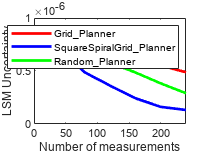


figure;
hold on;

box on;
plot(num_of_meas_interval:num_of_meas_interval:num_of_meas_sum,H1_M,'-','LineWidth',2,'color','r');
plot(num_of_meas_interval:num_of_meas_interval:num_of_meas_sum,H2_M,'-','LineWidth',2,'color','b');
plot(num_of_meas_interval:num_of_meas_interval:num_of_meas_sum,H3_M,'-','LineWidth',2,'color','g');
legend('Grid\_Planner','SquareSpiralGrid\_Planner','Random\_Planner');

xlabel('Number of measurements');
ylabel('LSM Uncertainty');


clc;
clear;
load('Base_Data.mat');

MAE1_BM = [];
H1_BM = [];
MAE2_BM = [];
H2_BM = [];
MAE3_BM = [];
H3_BM = [];
MAE_BM_MMI = [];
H_BM_MMI = [];

MAE_INIT = 0;

Building_Mon_number = 2;

MAXHeight = 129;
for b = 1:Building_Mon_number

BSHeight  = 129; %要进入下面的循环
while(BSHeight > 40) 

building_heights = create_BHM(MAXHeight);
%
BS2Dloc=[400,400];
Bsloc_BldHeight=max([building_heights(ceil(BS2Dloc(1)),ceil(BS2Dloc(2))), 
                     building_heights(ceil(BS2Dloc(1)),floor(BS2Dloc(2))),
                     building_heights(floor(BS2Dloc(1)),ceil(BS2Dloc(2))), 
                     building_heights(floor(BS2Dloc(1)),floor(BS2Dloc(2)))]);
BSHeight = Bsloc_BldHeight + 15;
% BSHeight = 15;



end

BSloc=[BS2Dloc,BSHeight];
% figure;
% mesh(building_heights);
% hold on;
% %BSHeight=Bsloc_BldHeight+0.01;%基站高度取建筑物上的20m
% plot3(BSloc(1),BSloc(2),BSloc(3),'r*','MarkerSize',10);
% legend('Buildings','BS');
UAVheight=max(max(building_heights));%139m,Building最大高度129m
% hold off;


%获取Building的3D坐标，每个（i，j）上的建筑物上的三维坐标，高度是建筑物最大高度
[NUM_X,NUM_Y]=size(building_heights);
Bld_grid_3Dloc=cell(NUM_X,NUM_Y);%NUM_X x NUM_Y x3 每个网格的3D位置
UAVgrid_Bs_dist=zeros(NUM_X,NUM_Y);
for i = 1:NUM_X
    for j = 1:NUM_Y
        temp = [i,j,building_heights(i,j)];
        Bld_grid_3Dloc{i,j} = temp;
        temp = [i,j,UAVheight];
        UAVgrid_Bs_dist(i,j) = norm(temp-BSloc);
    end
end

Map_grid = reshape(Bld_grid_3Dloc,[NUM_X*NUM_Y,1]);
Map_grid = cell2mat(Map_grid);
Map_grid(:,3) = UAVheight;
% 建立3D LSM, 范围[max(Build), max(Build+20)]
LSM = create_LSM(BSloc,building_heights,UAVheight);
% figure;
% imagesc(LSM');
% set(gca,'YDir','normal')
% colorbar;
% title('Real LSM')




I_Lphi_Mxn_initial = I_Lphi_Mxn;
num_Montercalo = 1;
MAE_M_MMI = [];
H_M_MMI = [];
num_of_meas_sum = 200;
num_of_meas_interval = 40;

for m  = num_Montercalo
I_Lphi_Mxn = I_Lphi_Mxn_initial;
MAE_MMI = [];
H_MMI = [];

num_of_meas = 0;

% 迭代寻找轨迹，直到满足一定条件结束无人机飞行。
maxInitial_I = max(max(I_Lphi_Mxn));
[row1,col1] = find(I_Lphi_Mxn == maxInitial_I); 
xI = [row1(1),col1(1)];
updated_grid_sum = [];

input_LSM = is_LoSorNLoS(BSloc,[xI,UAVheight],smallBldMap);
flag = -input_LSM + 2;
dI = norm([xI,UAVheight] - BSloc);

mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(dI);
var_g = Channel_Para(:,3); 
var_meas = 0;

zI = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量
[updated_grid,LSM_posterior, LSMlog_posterior] = Update_LSM(LSMlog_prior, [xI,UAVheight], zI, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图
updated_grid_sum = [updated_grid_sum;updated_grid];
num_of_meas = num_of_meas + 1;

[NUM_upa,~] = size(updated_grid);
for i = 1:NUM_upa % LSM地图，计算被更新的栅格角度上的求和的互信息
    xn = [updated_grid(i,1),updated_grid(i,2),UAVheight];
    I_Lphi_Mxn(xn(1),xn(2)) = Compute_I_Lphi_Mxn(LSM_posterior, xn, Channel_Para, BSloc);
end

maxInitial_I = max(max(I_Lphi_Mxn));
[row1,col1] = find(I_Lphi_Mxn == maxInitial_I); 
if size(row1,1) > 1
    [~, idx] = max(norm([row1,col1]-xI));
    xF = [row1(idx),col1(idx)];
else
    xF = [row1,col1];
end

numAngles  = 64; % 离散角度数量
stepLength = 40; % 测量步长

numMeas_sum = 0;
measurementPositions_sum  =  xI ;
LSM_posterior_mmi = {};

%% 更新初始位置和目的地，寻找寻找I_Lphi_Mxn中的最大值。

while 1
% disp(['已经进行到第',num2str(i),'次迭代飞行']);
updated_grid = [];


% xF = [row1(1),col1(1)];% 可能会有几个最大值。

% while norm(xF - xI) < 10 || i < 5
%     xF = [row1]
% end

[measurementPositions,resampledWaypoints] = Route_Planner_MMI(I_Lphi_Mxn,xI,xF,  BSloc, numAngles, stepLength);
measurementPositions_sum = [measurementPositions_sum;resampledWaypoints];

numMeas = size(resampledWaypoints,1);
numMeas_sum = numMeas_sum  +  numMeas;
for n = 1:numMeas
    xI_temp = xI;


    updated_gridn = [];
    LSMlog_prior = LSMlog_posterior;
    xn = [round(resampledWaypoints(n,1)),round(resampledWaypoints(n,2)),UAVheight];
    input_LSM = is_LoSorNLoS(BSloc,xn,smallBldMap);
    flag = -input_LSM + 2;
    dn = norm(xn - BSloc);

    mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(dn);
    var_g = Channel_Para(:,3); 
    var_meas = 0;
    
    zn = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量
    num_of_meas = num_of_meas + 1;
    

    [updated_gridn,LSM_posterior,LSMlog_posterior] = Update_LSM(LSMlog_prior, xn, zn, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图
    updated_grid = [updated_grid;updated_gridn];
    updated_grid = unique(updated_grid,'rows');

    if mod(num_of_meas,num_of_meas_interval) == 0
        LSM_posterior_mmi = [LSM_posterior_mmi,LSM_posterior];
    end


    if num_of_meas == num_of_meas_sum
        break;
    end
    
end
if num_of_meas == num_of_meas_sum
        break;
end

updated_grid_sum = [updated_grid_sum;updated_grid];
updated_grid_sum = unique(updated_grid_sum,'rows');
% 对更新后的LSM进行插值后再进行互信息计算.
% LSM_est_mmi = Interpolation_knn(updated_grid, LSM_posterior);


[NUM_upa,~] = size(updated_grid);
for j = 1:NUM_upa % LSM地图，计算被更新的栅格角度上的求和的互信息
    xn = [updated_grid(j,1),updated_grid(j,2),UAVheight];
    I_Lphi_Mxn(xn(1),xn(2)) = Compute_I_Lphi_Mxn(LSM_posterior, xn, Channel_Para, BSloc);
end

xI = xF;

maxInitial_I = max(max(I_Lphi_Mxn));
[row1,col1] = find(I_Lphi_Mxn == maxInitial_I); 
if size(row1,1) > 1
    [~, idx] = max(norm([row1,col1]-xI));
    xF = [row1(idx),col1(idx)];
else
    xF = [row1,col1];
end

end



for i = 1:length(LSM_posterior_mmi)
    MAE_MMI =   [MAE_MMI;sum(sum(abs(LSM_posterior_mmi{i} - LSM)))./(NUM_X*NUM_Y)];
    H_MMI = [H_MMI;Compute_H_LSM(LSM_posterior_mmi{i})./(NUM_X*NUM_Y)];
end
MAE_M_MMI = [MAE_M_MMI,MAE_MMI];
H_M_MMI = [H_M_MMI,H_MMI];




end

MAE_M_MMI = sum(MAE_M_MMI,2)./num_Montercalo;
H_M_MMI = sum(H_M_MMI,2)./num_Montercalo;




% 有不确定度信息熵和MAE两种指标
% 先在单种地图上进行蒙特卡洛测试


% num_of_meas_sum = 360;
% num_of_meas_interval = 40; % 测量数量间隔

% num_of_meas = 40:num_of_meas_interval:num_of_meas_sum;
% stepLength = 50;

route_plan_baseline = Route_planner_baseline;
measurementPositions_b1 = route_plan_baseline.Grid_planner(LSM,stepLength);
measurementPositions_b2 = route_plan_baseline.SquareSpiralGrid_planner(LSM,stepLength);
measurementPositions_b3 = route_plan_baseline.Random_planner(LSM,stepLength,num_of_meas_sum);
% MAE1 = zeros(floor(num_of_meas_sum./num_of_meas_interval),1);
% H1 = zeros(floor(num_of_meas_sum./num_of_meas_interval),1);

MAE1_M = [];
H1_M = [];
MAE2_M = [];
H2_M = [];
MAE3_M = [];
H3_M = [];
% num_Montercalo = 1;

for m = 1:num_Montercalo
    num_of_meas = 0;

%     measurementPositions_b1_m1 = measurementPositions_b1(1:num_of_meas(i),:);
%     measurementPositions_b2_m2 = measurementPositions_b2(1:num_of_meas(i),:);
%     measurementPositions_b3_m3 = measurementPositions_b3(1:num_of_meas(i),:);

    LSMlog_prior1 = log(LSM_initial./(1 - LSM_initial + eps));
    LSMlog_prior2 = log(LSM_initial./(1 - LSM_initial + eps));
    LSMlog_prior3 = log(LSM_initial./(1 - LSM_initial + eps));
    
    MAE1 = [];
    H1 = [];
    MAE2 = [];
    H2 = [];
    MAE3 = [];
    H3 = [];
    while num_of_meas < num_of_meas_sum

        for n = num_of_meas + 1:num_of_meas + num_of_meas_interval
            xn = [round(measurementPositions_b1(n,1)),round(measurementPositions_b1(n,2)),UAVheight];
            input_LSM = is_LoSorNLoS(BSloc,xn,smallBldMap);
            flag = -input_LSM + 2;
            dn = norm(xn - BSloc);
        
            mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(dn);
            var_g = Channel_Para(:,3); 
            var_meas = 0;
            
            zn = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量
            
            [~,LSM_posterior1,LSMlog_posterior1] = Update_LSM(LSMlog_prior1, xn, zn, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图

            LSMlog_prior1 = LSMlog_posterior1;
        end
        MAE1 = [MAE1;sum(sum(abs(LSM_posterior1 - LSM)))./(NUM_X*NUM_Y)];
        H1 = [H1;Compute_H_LSM(LSM_posterior1)./(NUM_X*NUM_Y)];
        

        for n = num_of_meas + 1:num_of_meas + num_of_meas_interval
            xn = [round(measurementPositions_b2(n,1)),round(measurementPositions_b2(n,2)),UAVheight];
            input_LSM = is_LoSorNLoS(BSloc,xn,smallBldMap);
            flag = -input_LSM + 2;
            dn = norm(xn - BSloc);
        
            mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(dn);
            var_g = Channel_Para(:,3); 
            var_meas = 0;
            
            zn = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量
            
            [~,LSM_posterior2,LSMlog_posterior2] = Update_LSM(LSMlog_prior2, xn, zn, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图

            LSMlog_prior2 = LSMlog_posterior2;
        end
        MAE2 = [MAE2;sum(sum(abs(LSM_posterior2 - LSM)))./(NUM_X*NUM_Y)];
        H2 = [H2;Compute_H_LSM(LSM_posterior2)./(NUM_X*NUM_Y)];


        for n = num_of_meas + 1:num_of_meas + num_of_meas_interval
            xn = [round(measurementPositions_b3(n,1)),round(measurementPositions_b3(n,2)),UAVheight];
            input_LSM = is_LoSorNLoS(BSloc,xn,smallBldMap);
            flag = -input_LSM + 2;
            dn = norm(xn - BSloc);
        
            mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(dn);
            var_g = Channel_Para(:,3); 
            var_meas = 0;
            
            zn = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量
            
            [~,LSM_posterior3,LSMlog_posterior3] = Update_LSM(LSMlog_prior3, xn, zn, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图

            LSMlog_prior3 = LSMlog_posterior3;
        end
        MAE3 = [MAE3;sum(sum(abs(LSM_posterior3 - LSM)))./(NUM_X*NUM_Y)];
        H3 = [H3;Compute_H_LSM(LSM_posterior3)./(NUM_X*NUM_Y)];

        num_of_meas = num_of_meas + num_of_meas_interval;
            
    end
        MAE1_M = [MAE1_M, MAE1];
        H1_M = [H1_M,H1];
        MAE2_M = [MAE2_M, MAE2];
        H2_M = [H2_M,H2];
        MAE3_M = [MAE3_M, MAE3];
        H3_M = [H3_M,H3];
        
end
MAE1_M = sum(MAE1_M,2)./num_Montercalo;
MAE2_M = sum(MAE2_M,2)./num_Montercalo;
MAE3_M = sum(MAE3_M,2)./num_Montercalo;
H1_M = sum(H1_M,2)./num_Montercalo;
H2_M = sum(H2_M,2)./num_Montercalo;
H3_M = sum(H3_M,2)./num_Montercalo;

MAE1_BM = [MAE1_BM, MAE1_M];
MAE2_BM = [MAE2_BM, MAE2_M];
MAE3_BM = [MAE3_BM, MAE2_M];
MAE_BM_MMI = [MAE_BM_MMI, MAE_M_MMI];

H1_BM = [H1_BM, H1_M];
H2_BM = [H2_BM, H2_M];
H3_BM = [H3_BM, H3_M];
H_BM_MMI = [H_BM_MMI, H_M_MMI];

MAE_INIT =  MAE_INIT + sum(sum(abs(LSM_initial - LSM)))./(NUM_X*NUM_Y);

end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125






MAE1_BM = sum(MAE1_BM,2)/Building_Mon_number;
MAE2_BM = sum(MAE2_BM,2)/Building_Mon_number;
MAE3_BM = sum(MAE3_BM,2)/Building_Mon_number;
MAE_BM_MMI = sum(MAE_BM_MMI,2)/Building_Mon_number;

H1_BM = sum(H1_BM,2)/Building_Mon_number;
H2_BM = sum(H2_BM,2)/Building_Mon_number;
H3_BM = sum(H3_BM,2)/Building_Mon_number;
H_BM_MMI = sum(H_BM_MMI,2)/Building_Mon_number;


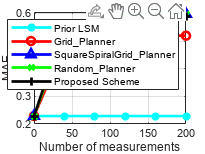



% MAE_INIT =  sum(sum(abs(LSM_initial - LSM)))./(NUM_X*NUM_Y);
MAE_INIT = MAE_INIT./Building_Mon_number;

H_INIT = Compute_H_LSM(LSM_initial)./(NUM_X*NUM_Y);

x_plot = 0:num_of_meas_interval:num_of_meas_sum;
figure;
% subplot(2,1,1);
hold on;

box on;

plot(0:num_of_meas_interval:num_of_meas_sum,MAE_INIT.*ones(size(x_plot,2),1),'-*','LineWidth',2,'color','cyan');
plot(0:num_of_meas_interval:num_of_meas_sum,[MAE_INIT;MAE1_BM],'-o','LineWidth',2,'color','r');
plot(0:num_of_meas_interval:num_of_meas_sum,[MAE_INIT;MAE2_BM],'-^','LineWidth',2,'color','b');
plot(0:num_of_meas_interval:num_of_meas_sum,[MAE_INIT;MAE3_BM],'-x','LineWidth',2,'color','g');
plot(0:num_of_meas_interval:num_of_meas_sum,[MAE_INIT;MAE_BM_MMI],'-+','LineWidth',2,'color','black');

lgd1 = legend('Prior LSM','Grid\_Planner','SquareSpiralGrid\_Planner','Random\_Planner','Proposed Scheme');
% 设置图例背景透明度
set(lgd1, 'Color', [1, 1, 1, 0]); % 最后一位为透明度，范围 [0, 1]
grid on;
xlabel('Number of measurements');
ylabel('MAE');

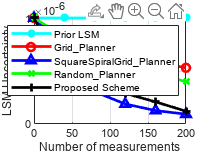


figure;
% subplot(2,1,2);
hold on;

box on;
plot(0:num_of_meas_interval:num_of_meas_sum,H_INIT.*ones(size(x_plot,2),1),'-*','LineWidth',2,'color','cyan');
plot(0:num_of_meas_interval:num_of_meas_sum,[H_INIT;H1_BM],'-o','LineWidth',2,'color','r');
plot(0:num_of_meas_interval:num_of_meas_sum,[H_INIT;H2_BM],'-^','LineWidth',2,'color','b');
plot(0:num_of_meas_interval:num_of_meas_sum,[H_INIT;H3_BM],'-x','LineWidth',2,'color','g');
plot(0:num_of_meas_interval:num_of_meas_sum,[H_INIT;H_BM_MMI],'-+','LineWidth',2,'color','black');

lgd2 = legend('Prior LSM','Grid\_Planner','SquareSpiralGrid\_Planner','Random\_Planner','Proposed Scheme');
% 设置图例背景透明度
set(lgd2, 'Color', [1, 1, 1, 0]); % 最后一位为透明度，范围 [0, 1]
grid on;
xlabel('Number of measurements');
ylabel('LSM Uncertainty');

I_Lphi_Mxn_initial = I_Lphi_Mxn;
num_Montercalo = 1;
MAE_M_MMI = [];
H_M_MMI = [];
num_of_meas_sum = 200;
num_of_meas_interval = 40;

for m  = num_Montercalo
I_Lphi_Mxn = I_Lphi_Mxn_initial;
MAE_MMI = [];
H_MMI = [];

num_of_meas = 0;

% 迭代寻找轨迹，直到满足一定条件结束无人机飞行。
maxInitial_I = max(max(I_Lphi_Mxn));
[row1,col1] = find(I_Lphi_Mxn == maxInitial_I); 
xI = [row1(1),col1(1)];
updated_grid_sum = [];

input_LSM = is_LoSorNLoS(BSloc,[xI,UAVheight],smallBldMap);
flag = -input_LSM + 2;
dI = norm([xI,UAVheight] - BSloc);

mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(dI);
var_g = Channel_Para(:,3); 
var_meas = 0;

zI = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量
[updated_grid,LSM_posterior, LSMlog_posterior] = Update_LSM(LSMlog_prior, [xI,UAVheight], zI, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图
updated_grid_sum = [updated_grid_sum;updated_grid];
num_of_meas = num_of_meas + 1;

[NUM_upa,~] = size(updated_grid);
for i = 1:NUM_upa % LSM地图，计算被更新的栅格角度上的求和的互信息
    xn = [updated_grid(i,1),updated_grid(i,2),UAVheight];
    I_Lphi_Mxn(xn(1),xn(2)) = Compute_I_Lphi_Mxn(LSM_posterior, xn, Channel_Para, BSloc);
end

maxInitial_I = max(max(I_Lphi_Mxn));
[row1,col1] = find(I_Lphi_Mxn == maxInitial_I); 
if size(row1,1) > 1
    [~, idx] = max(norm([row1,col1]-xI));
    xF = [row1(idx),col1(idx)];
else
    xF = [row1,col1];
end

numAngles  = 64; % 离散角度数量
stepLength = 40; % 测量步长

numMeas_sum = 0;
measurementPositions_sum  =  xI ;
LSM_posterior_mmi = {};

%% 更新初始位置和目的地，寻找寻找I_Lphi_Mxn中的最大值。

while 1
% disp(['已经进行到第',num2str(i),'次迭代飞行']);
updated_grid = [];


% xF = [row1(1),col1(1)];% 可能会有几个最大值。

% while norm(xF - xI) < 10 || i < 5
%     xF = [row1]
% end

[measurementPositions,resampledWaypoints] = Route_Planner_MMI(I_Lphi_Mxn,xI,xF,  BSloc, numAngles, stepLength);
measurementPositions_sum = [measurementPositions_sum;resampledWaypoints];

numMeas = size(resampledWaypoints,1);
numMeas_sum = numMeas_sum  +  numMeas;
for n = 1:numMeas
    xI_temp = xI;


    updated_gridn = [];
    LSMlog_prior = LSMlog_posterior;
    xn = [round(resampledWaypoints(n,1)),round(resampledWaypoints(n,2)),UAVheight];
    input_LSM = is_LoSorNLoS(BSloc,xn,smallBldMap);
    flag = -input_LSM + 2;
    dn = norm(xn - BSloc);

    mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(dn);
    var_g = Channel_Para(:,3); 
    var_meas = 0;
    
    zn = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量
    num_of_meas = num_of_meas + 1;
    

    [updated_gridn,LSM_posterior,LSMlog_posterior] = Update_LSM(LSMlog_prior, xn, zn, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图
    updated_grid = [updated_grid;updated_gridn];
    updated_grid = unique(updated_grid,'rows');

    if mod(num_of_meas,num_of_meas_interval) == 0
        LSM_posterior_mmi = [LSM_posterior_mmi,LSM_posterior];
    end


    if num_of_meas == num_of_meas_sum
        break;
    end
    
end
if num_of_meas == num_of_meas_sum
        break;
end

updated_grid_sum = [updated_grid_sum;updated_grid];
updated_grid_sum = unique(updated_grid_sum,'rows');
% 对更新后的LSM进行插值后再进行互信息计算.
% LSM_est_mmi = Interpolation_knn(updated_grid, LSM_posterior);


[NUM_upa,~] = size(updated_grid);
for j = 1:NUM_upa % LSM地图，计算被更新的栅格角度上的求和的互信息
    xn = [updated_grid(j,1),updated_grid(j,2),UAVheight];
    I_Lphi_Mxn(xn(1),xn(2)) = Compute_I_Lphi_Mxn(LSM_posterior, xn, Channel_Para, BSloc);
end

xI = xF;

maxInitial_I = max(max(I_Lphi_Mxn));
[row1,col1] = find(I_Lphi_Mxn == maxInitial_I); 
if size(row1,1) > 1
    [~, idx] = max(norm([row1,col1]-xI));
    xF = [row1(idx),col1(idx)];
else
    xF = [row1,col1];
end

end



for i = 1:length(LSM_posterior_mmi)
    MAE_MMI =   [MAE_MMI;sum(sum(abs(LSM_posterior_mmi{i} - LSM)))./(NUM_X*NUM_Y)];
    H_MMI = [H_MMI;Compute_H_LSM(LSM_posterior_mmi{i})./(NUM_X*NUM_Y)];
end
MAE_M_MMI = [MAE_M_MMI,MAE_MMI];
H_M_MMI = [H_M_MMI,H_MMI];




end

MAE_M_MMI = sum(MAE_M_MMI,2)./num_Montercalo;
H_M_MMI = sum(H_M_MMI,2)./num_Montercalo;




% 有不确定度信息熵和MAE两种指标
% 先在单种地图上进行蒙特卡洛测试


% num_of_meas_sum = 360;
% num_of_meas_interval = 40; % 测量数量间隔

% num_of_meas = 40:num_of_meas_interval:num_of_meas_sum;
% stepLength = 50;

route_plan_baseline = Route_planner_baseline;
measurementPositions_b1 = route_plan_baseline.Grid_planner(LSM,stepLength);
measurementPositions_b2 = route_plan_baseline.SquareSpiralGrid_planner(LSM,stepLength);
measurementPositions_b3 = route_plan_baseline.Random_planner(LSM,stepLength,num_of_meas_sum);
% MAE1 = zeros(floor(num_of_meas_sum./num_of_meas_interval),1);
% H1 = zeros(floor(num_of_meas_sum./num_of_meas_interval),1);

MAE1_M = [];
H1_M = [];
MAE2_M = [];
H2_M = [];
MAE3_M = [];
H3_M = [];
% num_Montercalo = 1;

for m = 1:num_Montercalo
    num_of_meas = 0;

%     measurementPositions_b1_m1 = measurementPositions_b1(1:num_of_meas(i),:);
%     measurementPositions_b2_m2 = measurementPositions_b2(1:num_of_meas(i),:);
%     measurementPositions_b3_m3 = measurementPositions_b3(1:num_of_meas(i),:);

    LSMlog_prior1 = log(LSM_initial./(1 - LSM_initial + eps));
    LSMlog_prior2 = log(LSM_initial./(1 - LSM_initial + eps));
    LSMlog_prior3 = log(LSM_initial./(1 - LSM_initial + eps));
    
    MAE1 = [];
    H1 = [];
    MAE2 = [];
    H2 = [];
    MAE3 = [];
    H3 = [];
    while num_of_meas < num_of_meas_sum

        for n = num_of_meas + 1:num_of_meas + num_of_meas_interval
            xn = [round(measurementPositions_b1(n,1)),round(measurementPositions_b1(n,2)),UAVheight];
            input_LSM = is_LoSorNLoS(BSloc,xn,smallBldMap);
            flag = -input_LSM + 2;
            dn = norm(xn - BSloc);
        
            mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(dn);
            var_g = Channel_Para(:,3); 
            var_meas = 0;
            
            zn = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量
            
            [~,LSM_posterior1,LSMlog_posterior1] = Update_LSM(LSMlog_prior1, xn, zn, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图

            LSMlog_prior1 = LSMlog_posterior1;
        end
        MAE1 = [MAE1;sum(sum(abs(LSM_posterior1 - LSM)))./(NUM_X*NUM_Y)];
        H1 = [H1;Compute_H_LSM(LSM_posterior1)./(NUM_X*NUM_Y)];
        

        for n = num_of_meas + 1:num_of_meas + num_of_meas_interval
            xn = [round(measurementPositions_b2(n,1)),round(measurementPositions_b2(n,2)),UAVheight];
            input_LSM = is_LoSorNLoS(BSloc,xn,smallBldMap);
            flag = -input_LSM + 2;
            dn = norm(xn - BSloc);
        
            mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(dn);
            var_g = Channel_Para(:,3); 
            var_meas = 0;
            
            zn = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量
            
            [~,LSM_posterior2,LSMlog_posterior2] = Update_LSM(LSMlog_prior2, xn, zn, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图

            LSMlog_prior2 = LSMlog_posterior2;
        end
        MAE2 = [MAE2;sum(sum(abs(LSM_posterior2 - LSM)))./(NUM_X*NUM_Y)];
        H2 = [H2;Compute_H_LSM(LSM_posterior2)./(NUM_X*NUM_Y)];


        for n = num_of_meas + 1:num_of_meas + num_of_meas_interval
            xn = [round(measurementPositions_b3(n,1)),round(measurementPositions_b3(n,2)),UAVheight];
            input_LSM = is_LoSorNLoS(BSloc,xn,smallBldMap);
            flag = -input_LSM + 2;
            dn = norm(xn - BSloc);
        
            mu_g = Channel_Para(:,1)+10.*Channel_Para(:,2).*log10(dn);
            var_g = Channel_Para(:,3); 
            var_meas = 0;
            
            zn = mu_g(flag) + sqrt(var_g(flag))*randn(1); % 获得一次测量
            
            [~,LSM_posterior3,LSMlog_posterior3] = Update_LSM(LSMlog_prior3, xn, zn, Channel_Para, LSM_initial, BSloc); % 在选出的测量位置测量来更新地图

            LSMlog_prior3 = LSMlog_posterior3;
        end
        MAE3 = [MAE3;sum(sum(abs(LSM_posterior3 - LSM)))./(NUM_X*NUM_Y)];
        H3 = [H3;Compute_H_LSM(LSM_posterior3)./(NUM_X*NUM_Y)];

        num_of_meas = num_of_meas + num_of_meas_interval;
            
    end
        MAE1_M = [MAE1_M, MAE1];
        H1_M = [H1_M,H1];
        MAE2_M = [MAE2_M, MAE2];
        H2_M = [H2_M,H2];
        MAE3_M = [MAE3_M, MAE3];
        H3_M = [H3_M,H3];
        
end
MAE1_M = sum(MAE1_M,2)./num_Montercalo;
MAE2_M = sum(MAE2_M,2)./num_Montercalo;
MAE3_M = sum(MAE3_M,2)./num_Montercalo;
H1_M = sum(H1_M,2)./num_Montercalo;
H2_M = sum(H2_M,2)./num_Montercalo;
H3_M = sum(H3_M,2)./num_Montercalo;


MAE_INIT = sum(sum(abs(LSM_initial - LSM)))./(NUM_X*NUM_Y);
H_INIT = Compute_H_LSM(LSM_initial)./(NUM_X*NUM_Y);

x_plot = 0:num_of_meas_interval:num_of_meas_sum;
figure;
% subplot(2,1,1);
hold on;

box on;

plot(0:num_of_meas_interval:num_of_meas_sum,MAE_INIT.*ones(size(x_plot,2),1),'-*','LineWidth',2,'color','cyan');
plot(0:num_of_meas_interval:num_of_meas_sum,[MAE_INIT;MAE1_M],'-o','LineWidth',2,'color','r');
plot(0:num_of_meas_interval:num_of_meas_sum,[MAE_INIT;MAE2_M],'-^','LineWidth',2,'color','b');
plot(0:num_of_meas_interval:num_of_meas_sum,[MAE_INIT;MAE3_M],'-x','LineWidth',2,'color','g');
plot(0:num_of_meas_interval:num_of_meas_sum,[MAE_INIT;MAE_M_MMI],'-+','LineWidth',2,'color','black');

lgd1 = legend('Prior LSM','Grid\_Planner','SquareSpiralGrid\_Planner','Random\_Planner','Proposed Scheme');
% 设置图例背景透明度
set(lgd1, 'Color', [1, 1, 1, 0]); % 最后一位为透明度，范围 [0, 1]
grid on;
xlabel('Number of measurements');
ylabel('MAE');

figure;
% subplot(2,1,2);
hold on;

box on;
plot(0:num_of_meas_interval:num_of_meas_sum,H_INIT.*ones(size(x_plot,2),1),'-*','LineWidth',2,'color','cyan');
plot(0:num_of_meas_interval:num_of_meas_sum,[H_INIT;H1_M],'-o','LineWidth',2,'color','r');
plot(0:num_of_meas_interval:num_of_meas_sum,[H_INIT;H2_M],'-^','LineWidth',2,'color','b');
plot(0:num_of_meas_interval:num_of_meas_sum,[H_INIT;H3_M],'-x','LineWidth',2,'color','g');
plot(0:num_of_meas_interval:num_of_meas_sum,[H_INIT;H_M_MMI],'-+','LineWidth',2,'color','black');

lgd2 = legend('Prior LSM','Grid\_Planner','SquareSpiralGrid\_Planner','Random\_Planner','Proposed Scheme');
% 设置图例背景透明度
set(lgd2, 'Color', [1, 1, 1, 0]); % 最后一位为透明度，范围 [0, 1]
grid on;
xlabel('Number of measurements');
ylabel('LSM Uncertainty');
